warning off
%C6
g = 9.82;
q = [0:0.5:3.5]'

q =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000


p6 = 1/g.*[5.75 5.85 5.9 5.7 5.1 4.25 3.3 2.4]'

p6 =     0.5855
    0.5957
    0.6008
    0.5804
    0.5193
    0.4328
    0.3360
    0.2444


p5 = 1/g.*[4.1 4.2 4.2 4 3.55 3 2.3 1.55]'

p5 =     0.4175
    0.4277
    0.4277
    0.4073
    0.3615
    0.3055
    0.2342
    0.1578


p3 = 1/g.*[1.75 1.85 1.7 1.3 0.95]'

p3 =     0.1782
    0.1884
    0.1731
    0.1324
    0.0967


p = [p6;p5;p3]

p =     0.5855
    0.5957
    0.6008
    0.5804
    0.5193
    0.4328
    0.3360
    0.2444
    0.4175
    0.4277


q = [q;q;q(1:5)]

q =          0
    0.5000
    1.0000
    1.5000
    2.0000
    2.5000
    3.0000
    3.5000
         0
    0.5000



w6 = repmat(80,8,1);
w5 = repmat(69,8,1);
w3 = repmat(48,5,1);
w = [w6;w5;w3]

w =     80
    80
    80
    80
    80
    80
    80
    80
    69
    69



A = [w.*w w.*q q.*q]

A = 	1.0e+03 *

    6.4000         0         0
    6.4000    0.0400    0.0003
    6.4000    0.0800    0.0010
    6.4000    0.1200    0.0022
    6.4000    0.1600    0.0040
    6.4000    0.2000    0.0063
    6.4000    0.2400    0.0090
    6.4000    0.2800    0.0123
    4.7610         0         0
    4.7610    0.0345    0.0003


b = p;
x = A\b  

x =     0.0001
    0.0004
   -0.0335


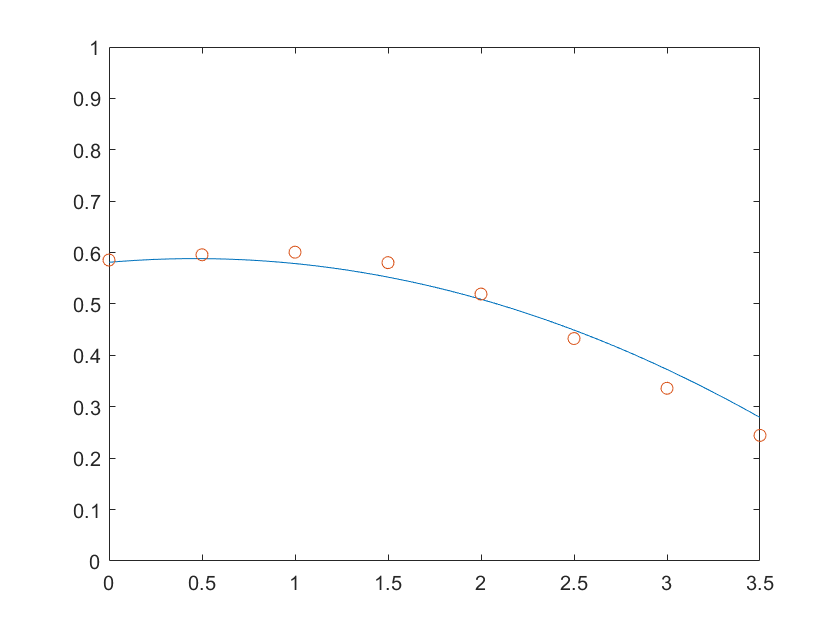


pumpcurve = @(q,w) x(1)*w^2+x(2)*q*w+x(3)*q^2;

pumpcurve6 = @(q) x(1)*80^2+x(2)*q*80+x(3)*q^2;

fplot(pumpcurve6)
hold on
scatter([0:0.5:3.5],p6)
hold off
xlim([0 3.5])
ylim([0 1])